# Goals: use ANN to fill the data gaps for LW net radiation 

## Load Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\BFLATANN\Radiation\'
cd data\input
load('Bflat30min.mat')

Bflat30min.OutRad_lw_Wm2(46980+134:46980+334) = NaN;
Bflat30min.OutRad_lw_Wm2(47315:47323) = NaN;
Bflat30min.OutRad_lw_Wm2(47113) = NaN;
Bflat30min.NetRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.InRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.OutRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.NetRad_Wm2(55244:60000) = NaN;

%Radiation
% figure, stackedplot(Bflat30min(:,[11,14,10,16,15,13,1]))
% title("BFLAT radiation") 

## Clip out bad radiation data

Bflat30min = sortrows(Bflat30min,'OutRad_lw_Wm2','descend');
Bflat30min(1:20700,:) = [];
Bflat30min = sortrows(Bflat30min,'Date_Time_MDT','ascend');
bflatEdCov = Bflat30min;
load('Bflat30min.mat')

# Subset Data - Input ANN BFLAT variables (InputVar) and training period (subset)

% min input - humidity, temp, time of day, wind speed, radiation

### Calculation with net Sw, net LW, and net rad (no pressure) %next do with no net rad

InputVar = [3,5,6,11,14,17] %Full radiation dataset - best results

InputVar =      3     5     6    11    14    17


InputVarStr = ['356111417']; %Paired down inputs - longer radiation continuity

fullmet = table2array(Bflat30min(:,InputVar));
subset = [1:length(bflatEdCov.AirTemp1_C)];


## Training data subset


figure
% stackedplot(bflatEdCov(subset,InputVar)); 
MetTrainingData = table2array(bflatEdCov(subset,InputVar));
LEfit = bflatEdCov.OutRad_lw_Wm2(subset); % Net LW radiation
LeAnnDateTime = Bflat30min.Date_Time_MDT;

% averaging = 'hourly';
% averaging = 'daily';
averaging = 'weekly';
% averaging = 'monthly';
% averaging = 'yearly';
iterations = 100

iterations = 100

## Loop - run model 100 times to compare the output

LeAnnModelOutput(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN]; %to make a vector of appropriate length to append to 
% LeAnnModelOutputVert(1:length(LeAnnDateTime), 1) = [NaN];
% LeAnnModelOutputVertYcolOrig = (1:length(LeAnnDateTime))';
LeAnnModelOutputCumSum(1:length(LeAnnDateTime), 1) = [NaN];
LeAnnModelOutputTrainingPeriod(1:length(MetTrainingData), 1) = [NaN]; %to make a vector of appropriate length to append to 
LeAnnModelOutputTrainingPeriodCumSum(1:length(MetTrainingData), 1) = [NaN];
for ii = 1:iterations %100 %change the number of iterations

# ANN script

    % Solve an Input-Output Fitting problem with a Neural Network
    % Script generated by Neural Fitting app
    % Created 10-Mar-2020 16:18:14
    %
    % This script assumes these variables are defined:
    %
    %   datamat - input data.
    %   LEfit - target data.
    
    x = MetTrainingData';
    t = LEfit';
    
    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems. -
    %bayesian regularization did >400 iterations, lm only does 20-70, typically r2 above 0.92. 
    % 'trainscg' uses less memory. Suitable in low memory situations. (WORST OPTION)
    trainFcn = 'trainbr';  % Levenberg-Marquardt backpropagation.
    
    % Create a Fitting Network
    hiddenLayerSize = 10;
    net = fitnet(hiddenLayerSize,trainFcn);
    
    % Setup Division of Data for Training, Validation, Testing
    net.divideParam.trainRatio = 40/100; %switch to 70
    net.divideParam.valRatio = 30/100; %switch to 25
    net.divideParam.testRatio = 30/100;
    
    % Train the Network
    [net,tr] = train(net,x,t);
    
    % Test the Network
    y = net(x);
    e = gsubtract(t,y);
    performance = perform(net,t,y)
    
    % View the Network
    %  view(net)
    
    % Plots
    % Uncomment these lines to enable various plots.
    % figure, plotperform(tr)
    % figure, plottrainstate(tr)
    % figure, ploterrhist(e)
    %% CAN UNCOMMENT DATA WITH #
    % # plotregression(t,y)
    %# print('ModelFit','-bestfit','-dpdf') 
    %figure, plotfit(net,x,t)
    %plotfit(net,y,t)
    

### Apply to full dataset

    LEann = net(fullmet');
    LEann = LEann';
    LEann = fillmissing(LEann, "linear");
    LeAnnModelOutput = [LeAnnModelOutput, LEann];
    LeAnnModelOutputCumSum = [LeAnnModelOutputCumSum, cumsum(fillmissing(LEann, "linear"))];
    % LeAnnModelOutputVert = [LeAnnModelOutputVert; LEann];
    % LeAnnModelOutputVertYcol = [LeAnnModelOutputVertYcol; LeAnnModelOutputVertYcolOrig]; %half of what it should be.
    
    LeAnnModelOutputTrainingPeriod = [LeAnnModelOutputTrainingPeriod, y'];
    LeAnnModelOutputTrainingPeriodCumSum = [LeAnnModelOutputTrainingPeriodCumSum, cumsum(fillmissing(y', "linear"))];    
end

performance = 20.7037

performance = 20.7044

performance = 20.6125

performance = 20.7205

performance = 20.6886

performance = 20.7004

performance = 20.7118

performance = 20.6826

performance = 20.6397

performance = 20.7511

performance = 20.5905

performance = 20.7310

performance = 20.6175

performance = 20.6592

performance = 20.6850

performance = 20.6976

performance = 20.6812

performance = 20.6559

performance = 20.6959

performance = 20.7358

performance = 20.7277

performance = 20.6662

performance = 20.6946

performance = 20.5525

performance = 20.7678

performance = 20.6837

performance = 20.6346

performance = 20.6063

performance = 20.6599

performance = 9.2716e+03

performance = 1.5732e+04

performance = 1.5677e+05

performance = 1.5976e+04

performance = 1.8170e+04

performance = 1.8071e+04

performance = 1.6441e+04

performance = 1.1693e+04

performance = 4.0699e+04

performance = 5.8141e+03

performance = 4.5444e+04

performance = 2.0455e+04

performance = 1.3341e+04

performance = 4.8988e+04

performance = 9.0640e+03

performance = 1.2023e+04

performance = 6.8969e+03

performance = 4.6277e+04

performance = 4.8911e+04

performance = 5.4231e+04

performance = 2.2744e+03

performance = 3.9206e+04

performance = 5.6593e+04

performance = 1.1972e+04

## Compare fit quality 

clear y performance x hiddenLayerSize trainFcn tr LEann e t ii net
LeAnnModelOutputTrainingPeriod(:,1) = [];
% LeAnnModelOutputTrainingPeriod = transpose(mean(transpose(LeAnnModelOutputTrainingPeriod)));
LeAnnModelOutputTrainingPeriodCumSum50 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[50],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum25 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[25],2); %maywanttoreconsider naming here
LeAnnModelOutputTrainingPeriodCumSum75 = prctile((LeAnnModelOutputTrainingPeriodCumSum(:,1:end)),[75],2); %maywanttoreconsider naming here

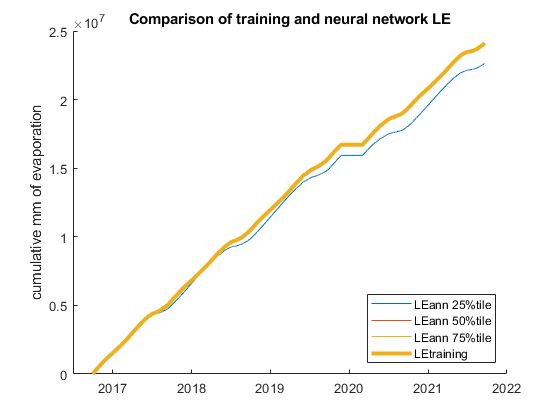


figure
hold on
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum25, 'DisplayName', 'LEann 25%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum50, 'DisplayName', 'LEann 50%tile')
plot(bflatEdCov.Date_Time_MDT, LeAnnModelOutputTrainingPeriodCumSum75, 'DisplayName', 'LEann 75%tile')
plot(bflatEdCov.Date_Time_MDT, cumsum(fillmissing(bflatEdCov.OutRad_lw_Wm2(subset), "linear")), ...
    'color', [0.9290 0.6940 0.1250],'linewidth', 3,  'DisplayName','LEtraining')
legend('location', 'southeast')
ylabel("cumulative mm of evaporation")
title('Comparison of training and neural network LE')

clear LeAnnModelOutputTrainingPeriodCumSum75 LeAnnModelOutputTrainingPeriodCumSum50 LeAnnModelOutputTrainingPeriodCumSum25

## OUTPUT = LEann calculated for entire dataset

Bflat30min(:,2:end) = [];
Bflat30min.LEann_mean = transpose(mean(transpose(LeAnnModelOutput(:,2:end))));
% Bflat30min.LEann_std = transpose(std(transpose(LeAnnModelOutput(:,2:end))));
Bflat30min.LEann_prctile25 = prctile((LeAnnModelOutput(:,2:end)),[25],2); %calculate percentiles
Bflat30min.LEann_prctile50 = prctile((LeAnnModelOutput(:,2:end)),[50],2); %calculate percentiles
Bflat30min.LEann_prctile75 = prctile((LeAnnModelOutput(:,2:end)),[75],2); %calculate percentiles

Bflat30min.LEann_CumSum_mean = transpose(mean(transpose(LeAnnModelOutputCumSum(:,2:end))));
Bflat30min.LEann_CumSum_prctile25 = prctile((LeAnnModelOutputCumSum(:,2:end)),[25],2); %calculate percentiles
Bflat30min.LEann_CumSum_prctile50 = prctile((LeAnnModelOutputCumSum(:,2:end)),[50],2); %calculate percentiles
Bflat30min.LEann_CumSum_prctile75 = prctile((LeAnnModelOutputCumSum(:,2:end)),[75],2); %calculate percentiles

Bflat30min(:,1) = [];

OUTPUT = array2table(LeAnnModelOutput(:,2:end));
OUTPUT.Date_Time = LeAnnDateTime;
OUTPUT = table2timetable(OUTPUT);
%%

### Affect of changing different study periods

OUTPUT = retime(OUTPUT, averaging, 'sum');
BFLATnew = retime(Bflat30min, averaging, 'mean'); %Does not work on rain values... 
BFLATnew(:,2:end) = [];

### Leave this the same

OUTPUT =  timetable2table(OUTPUT);
OUTPUT(:,1) = []; %remove time column 
OUTPUT = table2array(OUTPUT);

### Percentile seems effective, but large difference between 50th percentile and mean

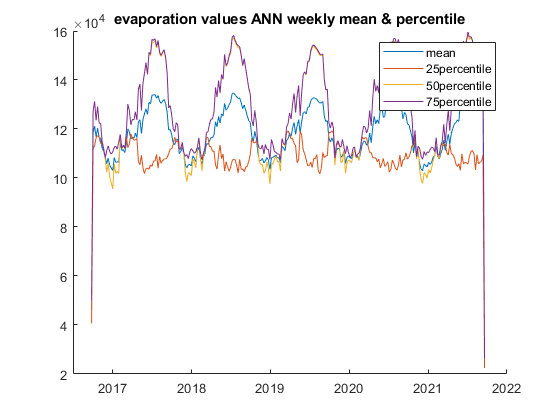

BFLATnew.LEann_mean = transpose(mean(transpose(OUTPUT)));
BFLATnew.LEann_prctile25 = prctile(OUTPUT,[25],2); %calculate percentiles
BFLATnew.LEann_prctile50 = prctile(OUTPUT,[50],2); %calculate percentiles
BFLATnew.LEann_prctile75 = prctile(OUTPUT,[75],2); %calculate percentiles

% BFLATnew(:,1) = [];

figure
hold on 

% plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_mean + BFLATnew.LEann_std, 'DisplayName', 'Standard deviation')
% plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_mean - BFLATnew.LEann_std, 'DisplayName', 'Standard deviation')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_mean, 'DisplayName', 'mean')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile25, 'DisplayName', '25percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile50, 'DisplayName', '50percentile')
plot(BFLATnew.Date_Time_MDT, BFLATnew.LEann_prctile75, 'DisplayName', '75percentile')
% plot(BFLATnew.Date_Time_MDT, BFLATnew.LeAnnModelOutput./BFLATnew.LeAnnModelOutput, 'DisplayName', 'Standard deviation/MEAN')
legend
title(['evaporation values ANN ',averaging,' mean & percentile'])
hold off

### Show cumulative sum of weekly averages?  title(['evaporation values ANN ',averaging,' averages'])

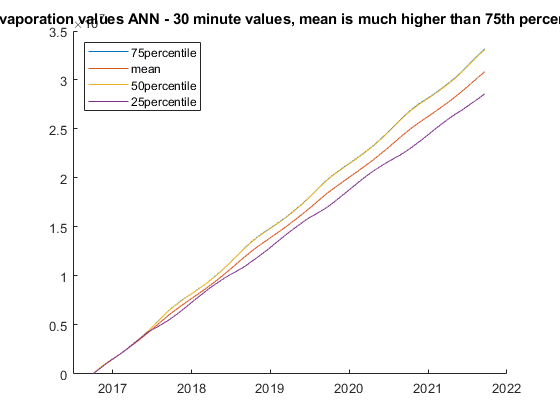

figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_CumSum_prctile25, 'DisplayName', '25percentile')
legend('location', 'northwest')
title("evaporation values ANN - 30 minute values, mean is much higher than 75th percentile")
hold off

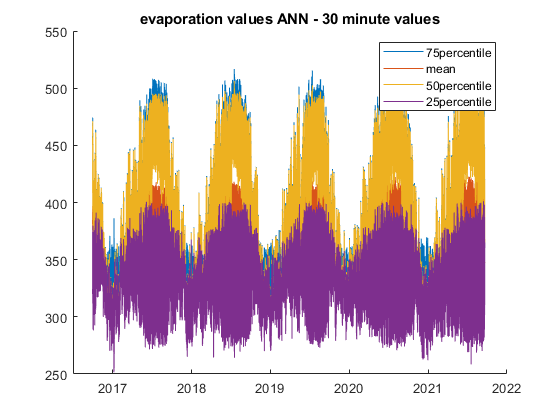


figure
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile75, 'DisplayName', '75percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_mean, 'DisplayName', 'mean')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile50, 'DisplayName', '50percentile')
plot(Bflat30min.Date_Time_MDT, Bflat30min.LEann_prctile25, 'DisplayName', '25percentile')
legend
title("evaporation values ANN - 30 minute values")
hold off

clear bflatEdCov fullmet InputVar LeAnnDateTime LeAnnModelOutput LeAnnModelOutputCumSum 
clear LeAnnModelOutputTrainingPeriodCumSum LeAnnModelOutputTrainingPeriod LEfit
clear OUTPUT MetTrainingData subset

# Save Data

cd ../output/
eval(['Bflat_30minLEann_',InputVarStr, ' = Bflat30min;'])
Bflat_30minLEann_356111417.Properties.VariableNames{3} = 'OutRad_lw_Wm2_ANN';

% Bflat_30minLEann_356111417([43240:51690],:) = [];

Bflat_30min_ann_outLW = Bflat_30minLEann_356111417; 

InputVarStr;
% writetimetable(Bflat_30min_ann_outLW)
save('Bflat_30min_ann_outLW.mat','Bflat_30min_ann_outLW')
% writetimetable(BFLAT_weeklyLEann_356111417)
% save('BFLAT_weeklyLEann_356111417.mat','BFLAT_weeklyLEann_356111417')
